## MATLAB Code to Sketch an m = -1 Hyperabrupt Profile of an n+ to p junction

### Define the position vectors for the n+ and p regions 

(Sampling x_p and x_n)

x_n = -5:0.1:0; % n+ region from -5 to 0 arbitrary units
x_p = 0:0.1:5; % p region from 0 to 5 arbitrary units


### Define the dopant concentration profiles

- For n+ region, assume a hyperabrupt profile with m = -1

- This would be a linear function on a log scale

- For simplicity, we use an arbitrary linear function to represent this

- Using usual values for N_D and N_A

N_D = 10^18 * exp(-x_n); % exponential decay for n+ region
% For p region, assume a constant acceptor concentration
N_A = 10^17 * ones(size(x_p)); % constant for p region


### Combine the data for plotting

x = [x_n, x_p];
N = [N_D, N_A];


### Plot the profile

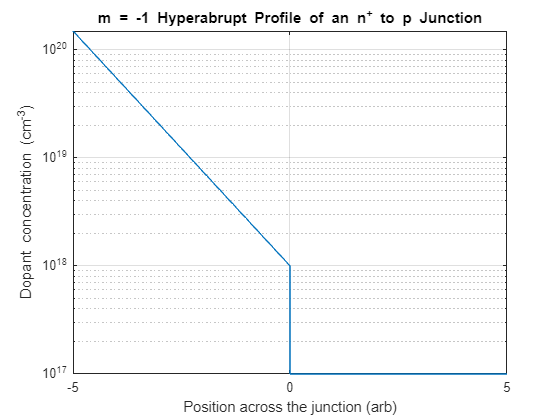

figure;
semilogy(x, N);
xlabel('Position across the junction (arb)');
ylabel('Dopant concentration (cm^{-3})');
title('m = -1 Hyperabrupt Profile of an n^+ to p Junction');
grid on;